# This is a MATLAB live script for analyzing the first guesses of reponses to Guess the Number game

small interval: [1    10], n = 6

mid interval: [1    1,000], n = 43

big interval: [1    100,000], n = 23

## Analysis for Mid sized interval

MAX = 1000; % endpoint of interval (depends on which experiment)
% This is the data for the first guess of participants who played the
% mid-sized interval ([1, 1000]) version of the "Guess the Number" game
data = [590, 500, 7, 400, 500, 800, 500, 69, 500, 500, 22, 500, 56, 500, 100, ...
    500, 200, 9, 500, 500, 500, 500, 877, 2, 1, 700, 45, 250, 500, 234, 239, ...
    500, 921, 7, 500, 500, 500, 500, 500, 529, 764, 500, 500]';
% create a logical vector of whether person knows bisection search
class = logical([1, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 1, 1, 1, 0, 1, 0, 1, 1, 1, ...
    1, 1, 0, 0, 1, 0, 1, 1, 0, 0, 0, 1, 0, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1]); % 1 if participant knew Bisection Search
n = length(data)

n = 43

disp(["mean of first guess", num2str(mean(data))])

    "mean of first guess"    "402.8372"



disp(["standard deviation of first guess", num2str(std(data))])

    "standard deviation of first guess"    "250.0489"



gauss = makedist('Normal', 'mu', MAX/2, 'sigma', std(data)); % N(mu=500, sigma=std), std estimated from data
unif = makedist('Uniform', "lower", 1, "upper", MAX); % Uniform(a=1, b=1000)

#### Analysis of complete data (both types of people)

binEdges = linspace(0,MAX,12) % this ensure a bin is centered at midpoint

binEdges = 	1.0e+03 *

         0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000


hist = histogram(data, 'BinEdges', binEdges);
hold on
binCenters = binEdges(1:end-1) + diff(binEdges)/2

binCenters =    45.4545  136.3636  227.2727  318.1818  409.0909  500.0000  590.9091  681.8182  772.7273  863.6364  954.5455


obsCounts = hist.BinCounts % frequency 

obsCounts =      9     1     4     0     1    22     1     1     2     1     1


expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))); % expected counts using Uniform distribution
expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution

expCounts2 =      2     2     3     5     6     6     6     5     3     2     2


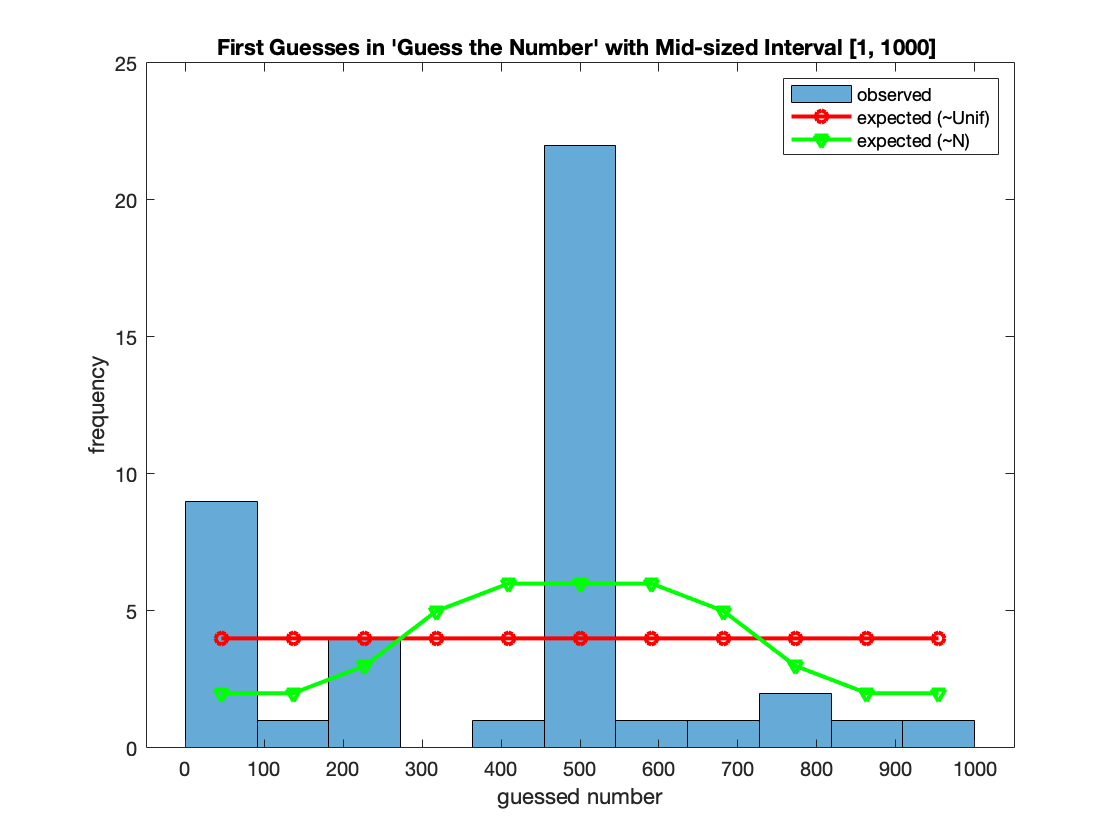

plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
xlabel("guessed number"); ylabel("frequency"); 
title("First Guesses in 'Guess the Number' with Mid-sized Interval [1, 1000] ")
legend("observed", "expected (~Unif)", "expected (~N)")
hold off

% Perform Chi-Squared to test if the data is Gaussian with mean 500
[h,p,st] = chi2gof(data, 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data

h = 1

p = 1.5623e-10

st = struct with fields:
    chi2stat: 51.7414
          df: 4
       edges: [1.0000 369.0000 461.0000 553.0000 645.0000 921.0000]
           O: [14 1 22 1 5]
           E: [12.9075 5.9277 6.2738 5.8082 12.0828]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess is NOT Gaussian with mean 500


% Perform Chi-Squared to test if the data is Uniformly distributed
[h,p,st] = chi2gof(data, 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform

h = 0

p = 0.1420

st = struct with fields:
    chi2stat: 2.1566
          df: 1
       edges: [1.0000 461.0000 921.0000]
           O: [15 28]
           E: [19.7998 23.2002]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniformly distributed")
else
    disp("Chi-squared: The first guess may be Uniformly distributed")
end

Chi-squared: The first guess may be Uniformly distributed


#### Persons who knew Binary/Bisection Search 

% % People who knew bisection search
% hist = histogram(data(class), 'BinEdges', binEdges);
% gauss.sigma = std(data(class)); % estimate standard deviation
% hold on
% obsCounts = hist.BinCounts % frequency 
% expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution
% expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution
% plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
% plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
% xlabel("guessed number"); ylabel("frequency"); 
% title('First guess with prior knowledge of bisection search')
% legend("observed", "expected (~Unif)", "expected (~N)")
% hold off
% % Perform Chi-Squared to test if the data is Gaussian with mean 500
% [h,p,st] = chi2gof(data(class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data
% if h == 1
%     disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
% else
%     disp("Chi-squared: The first guess may be Gaussian with mean 500")
% end
% % Perform Chi-Squared to test if the data is Uniformly distributed
% [h,p,st] = chi2gof(data(class), 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform
% if h == 1
%     disp("Chi-squared: The first guess is NOT Uniformly distributed")
% else
%     disp("Chi-squared: The first guess may be Uniformly distributed")
% end
% % Since Chi-square test rejected, model the first guess of people 
% % who knew binary search as Bernoulli p(500) = 1-alpha, alpha << 0.5
% p500 = sum(data(class)==MAX/2)/length(data(class))
% % simulate data (pick 500 with P=p500, pick any other number with P=1-p500)
% 

#### Persons who did NOT know Binary/Bisection Search 

% % People who did not know bisection search
% hist = histogram(data(~class), 'BinEdges', binEdges);
% gauss.sigma = std(data(~class)); % estimate standard deviation
% hold on
% obsCounts = hist.BinCounts % frequency 
% expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution
% expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution
% plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
% plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
% xlabel("guessed number"); ylabel("frequency"); 
% title('First guess without prior knowldege')
% legend("observed", "expected (~Unif)", "expected (~N)")
% hold off
% % Perform Chi-Squared to test if the data is Gaussian with mean 500
% [h,p,st] = chi2gof(data(~class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data
% if h == 1
%     disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
% else
%     disp("Chi-squared: The first guess may be Gaussian with mean 500")
% end
% % Perform Chi-Squared to test if the data is Uniformly distributed
% [h,p,st] = chi2gof(data(~class), 'CDF', unif, 'NParams', 0) % no parameters estimated for Uniform
% if h == 1
%     disp("Chi-squared: The first guess is NOT Uniformly distributed")
% else
%     disp("Chi-squared: The first guess may be Uniformly distributed")
% end

## Same analysis for Big interval

MAX = 100000; % endpoint of interval (depends on which experiment)
% This is the data for the first guess of participants who played the
% large-sized interval ([1, 100000]) version of the "Guess the Number" game
data = [30000, 50, 50000, 500, 50000, 1, 5000, 80000, 10, 1, 50000, 50000, 500, ...
    50000, 5000, 50000, 50000, 2, 50000, 500, 50000, 600, 50000]';
% create a logical vector of whether person knows bisection search
class = logical([0, 1, 1, 0, 1, 0, 1, 1, 0, 1, 1, 1, 0, 1,...
    0, 0, 1, 0, 1, 1, 0, 0, 1]); % 1 if participant knew Bisection Search
n = length(data)

n = 23

disp(["mean of first guess", num2str(mean(data))])

    "mean of first guess"    "27050.6087"



disp(["standard deviation of first guess", num2str(std(data))])

    "standard deviation of first guess"    "26561.4191"



gauss = makedist('Normal', 'mu', MAX/2, 'sigma', std(data)); % N(mu=500, sigma=std), std estimated from data
unif = makedist('Uniform', "lower", 1, "upper", MAX); % Uniform(a=1, b=100,000)

#### Analysis of complete data (both types of people)

binEdges = linspace(0,MAX,12) % this ensure a bin is centered at midpoint

binEdges = 	1.0e+05 *

         0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000


hist = histogram(data, 'BinEdges', binEdges);
hold on
binCenters = binEdges(1:end-1) + diff(binEdges)/2

binCenters = 	1.0e+04 *

    0.4545    1.3636    2.2727    3.1818    4.0909    5.0000    5.9091    6.8182    7.7273    8.6364    9.5455


obsCounts = hist.BinCounts % frequency 

obsCounts =     11     0     0     1     0    10     0     0     1     0     0


expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))); % expected counts using Uniform distribution
expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution

expCounts2 =      1     1     2     2     3     3     3     2     2     1     1


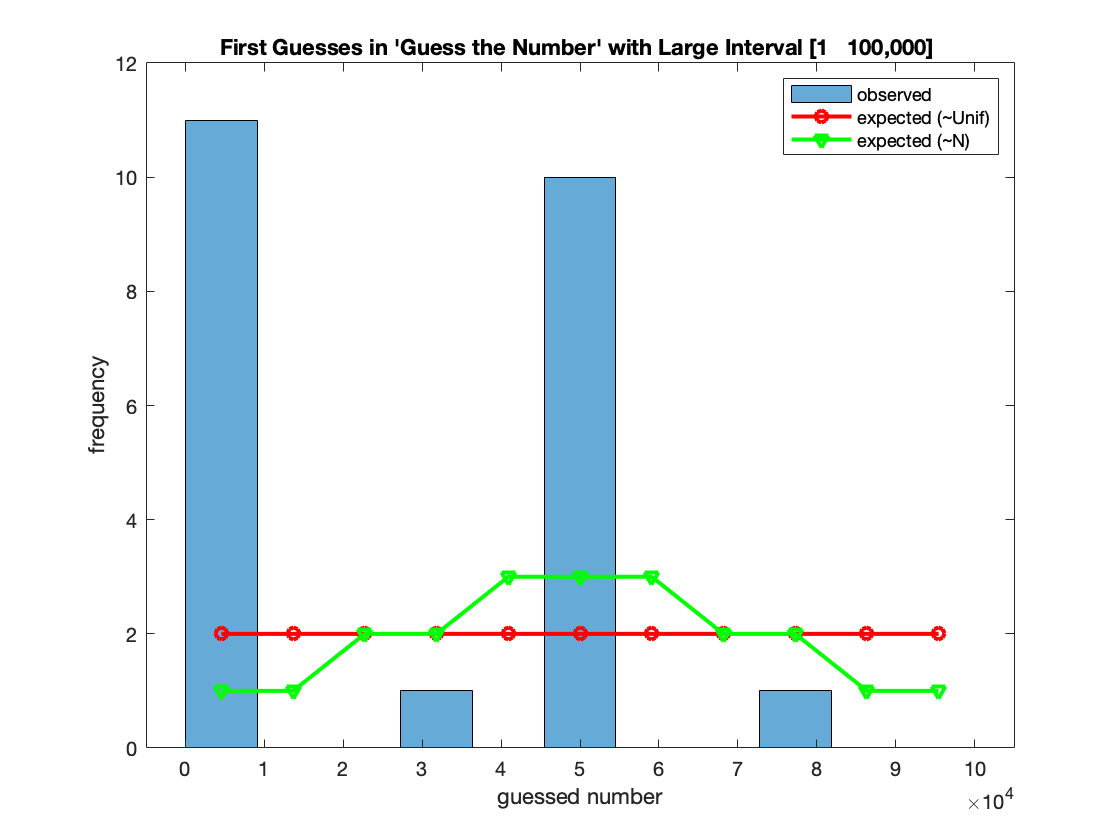

plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
xlabel("guessed number"); ylabel("frequency"); 
title("First Guesses in 'Guess the Number' with Large Interval [1   100,000] ")
legend("observed", "expected (~Unif)", "expected (~N)")
hold off

% Perform Chi-Squared to test if the data is Gaussian with mean 500
[h,p,st] = chi2gof(data, 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data

h = 0

p = 0.6190

st = struct with fields:
    chi2stat: 0.2472
          df: 1
       edges: [1.0000 4.8000e+04 8.0000e+04]
           O: [12 11]
           E: [10.8099 12.1901]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 50,000")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 50,000")
end

Chi-squared: The first guess may be Gaussian with mean 50,000


% Perform Chi-Squared to test if the data is Uniformly distributed
[h,p,st] = chi2gof(data, 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform

h = 0

p = 0.6887

st = struct with fields:
    chi2stat: 0.1605
          df: 1
       edges: [1.0000 4.8000e+04 8.0000e+04]
           O: [12 11]
           E: [11.0400 11.9600]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniformly distributed")
else
    disp("Chi-squared: The first guess may be Uniformly distributed")
end

Chi-squared: The first guess may be Uniformly distributed


#### Persons who knew Binary/Bisection Search 

% % People who knew bisection search
% hist = histogram(data(class), 'BinEdges', binEdges);
% gauss.sigma = std(data(class)); % estimate standard deviation
% hold on
% obsCounts = hist.BinCounts % frequency 
% expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution
% expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution
% plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
% plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
% xlabel("guessed number"); ylabel("frequency"); 
% title('First guess with prior knowledge of bisection search')
% legend("observed", "expected (~Unif)", "expected (~N)")
% hold off
% % Perform Chi-Squared to test if the data is Gaussian with mean 500
% [h,p,st] = chi2gof(data(class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data
% if h == 1
%     disp("Chi-squared: The first guess is NOT Gaussian with mean 50,000")
% else
%     disp("Chi-squared: The first guess may be Gaussian with mean 50,000")
% end
% % Perform Chi-Squared to test if the data is Uniformly distributed
% [h,p,st] = chi2gof(data(class), 'CDF', unif, 'NParams', 0) % no [araneters estimated for Uniform
% if h == 1
%     disp("Chi-squared: The first guess is NOT Uniformly distributed")
% else
%     disp("Chi-squared: The first guess may be Uniformly distributed")
% end
% % Since Chi-square test rejected, model the first guess of people 
% % who knew binary search as Bernoulli p(500) = 1-alpha, alpha << 0.5
% pMid = sum(data(class)==MAX/2)/length(data(class))
% % simulate data (pick 50,000 with P=pMid, pick any other number with P=1-pMid)
% 

#### Persons who did NOT know Binary/Bisection Search 

% % People who did not know bisection search
% hist = histogram(data(~class), 'BinEdges', binEdges);
% gauss.sigma = std(data(~class)); % estimate standard deviation
% hold on
% obsCounts = hist.BinCounts % frequency 
% expCounts1 = round(n * diff(cdf(unif, [-inf binEdges(2:end-1) inf]))) % expected counts using Uniform distribution
% expCounts2 = round(n * diff(cdf(gauss, [-inf binEdges(2:end-1) inf]))) % expected counts using Normal distribution
% plot(binCenters, expCounts1,'LineWidth',2, 'Color', 'r', "Marker", "o")
% plot(binCenters, expCounts2,'LineWidth',2, 'Color', 'g', "Marker", "v")
% xlabel("guessed number"); ylabel("frequency"); 
% title('First guess without prior knowldege')
% legend("observed", "expected (~Unif)", "expected (~N)")
% hold off
% % Perform Chi-Squared to test if the data is Gaussian with mean 500
% [h,p,st] = chi2gof(data(~class), 'CDF', gauss, 'NParams', 1) % nparams=1 because sigma estimated from data
% if h == 1
%     disp("Chi-squared: The first guess is NOT Gaussian with mean 50,000")
% else
%     disp("Chi-squared: The first guess may be Gaussian with mean 50,000")
% end
% % Perform Chi-Squared to test if the data is Uniformly distributed
% [h,p,st] = chi2gof(data(~class), 'CDF', unif, 'NParams', 0) % no parameters estimated for Uniform
% if h == 1
%     disp("Chi-squared: The first guess is NOT Uniformly distributed")
% else
%     disp("Chi-squared: The first guess may be Uniformly distributed")
% end